clc;clear;

Parámetros

load('DatosGradiente.mat')
N=length(y); M=20000; 
alpha=5;
na=4; nb=1;
a0=0*ones(1,na); b0=0*ones(1,nb); %Valores iniciales de ai y bi
a=zeros(M,na);b=zeros(M,nb); a(1,:)=a0; b(1,:)=b0;
V=zeros(M,1);
Ts=9;
t=(0:Ts:(N-1)*Ts)';
tol=10^(-7);

uF=lsim(tf([1 zeros(1,na)],[1 a(1,:)],'Ts',Ts),u,t); %Filtro de la entrada
yest=lsim(tf([b(1,:) zeros(1,max(na-nb,0))],[1 a(1,:) zeros(1,max(nb-na,0))],'Ts',Ts),u,t); %Predictor optimo
yestF=lsim(tf([1 zeros(1,na)],[1 a(1,:)],'Ts',Ts),yest,t); %Filtro de la salida estimada
e=y(2:N)-yest(2:N); V(1)=e'*e/N; %Error y función de coste
DVa=inf(1,na);
DVb=inf(1,nb);
i=1;
while i<=M && norm([DVa DVb])>tol
    i=i+1;
    for j=1:na
        DVa(j)=(2/N)*e(j:N-1)'*yestF(1:N-j); %Gradiente para ai
    end
    for j=1:nb
        DVb(j)=-(2/N)*e(j:N-1)'*uF(1:N-j); %Gradiente para bi
    end 
    a(i,:)=a(i-1,:)-alpha*DVa;
    b(i,:)=b(i-1,:)-alpha*DVb;
    uF=lsim(tf([1 zeros(1,na)],[1 a(i,:)],'Ts',Ts),u,t); %Filtro de la entrada
    yest=lsim(tf([b(i,:) zeros(1,max(na-nb,0))],[1 a(i,:) zeros(1,max(nb-na,0))],'Ts',Ts),u,t); %Predictor optimo
    yestF=lsim(tf([1 zeros(1,na)],[1 a(i,:)],'Ts',Ts),yest,t); %Filtro de la salida estimada
    e=y(2:N)-yest(2:N); V(i)=e'*e/N; %Error y función de coste
end
V=V(1:i);
a=a(1:i,:);
b=b(1:i,:);

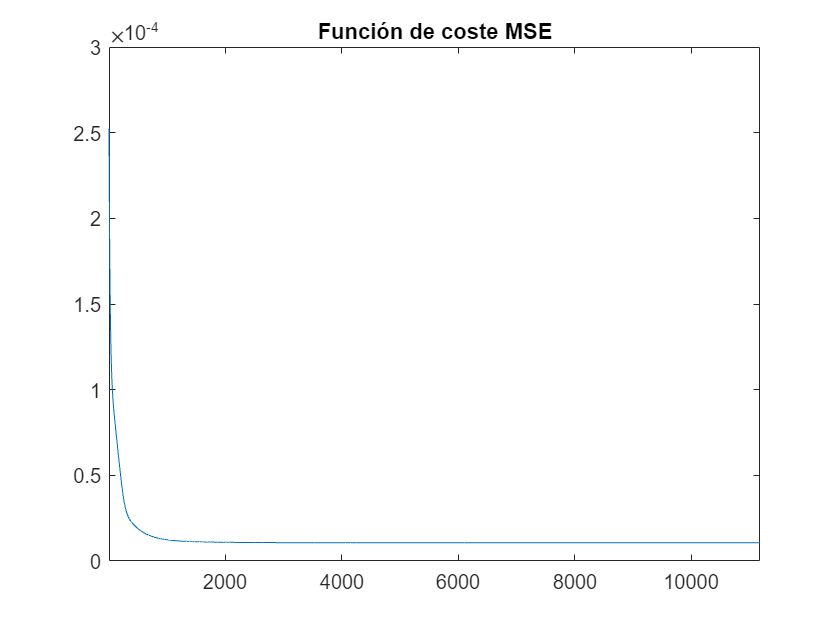

plot(1:i,V)
xlim([1,i])
title("Función de coste MSE")

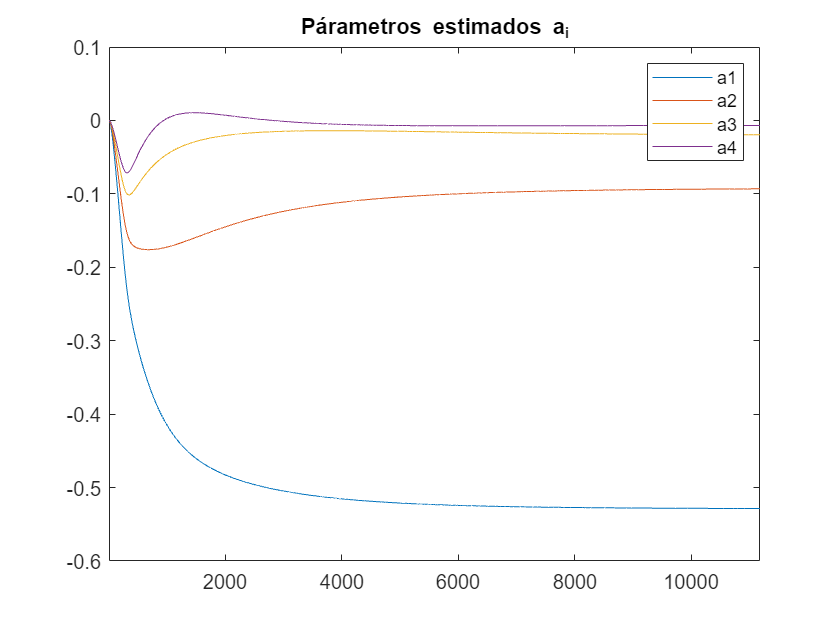

plot(1:i,a)
xlim([1,i])
legend('a'+string(1:na))
title("Párametros estimados a_{i}")

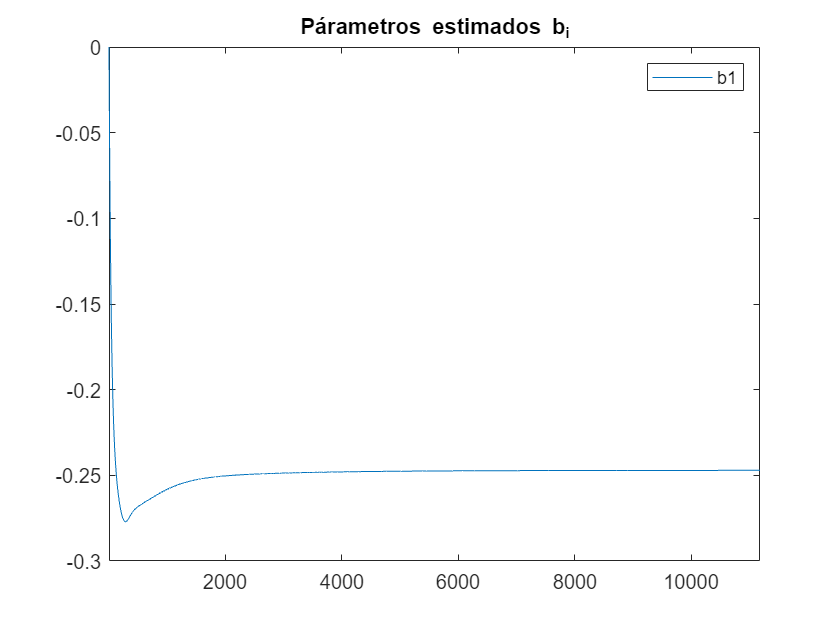

plot(1:i,b)
xlim([1,i])
legend('b'+string(1:nb))
title("Párametros estimados b_{i}")

%yest=lsim(tf(b(i),[1 a(i) 0 0 0],'Ts',Ts),u,t);

tf([b(i,:) zeros(1,max(na-nb,0))],[1 a(i,:) zeros(1,max(nb-na,0))],'Ts',Ts)

ans =
 
                       -0.2471 z^3
  -----------------------------------------------------
  z^4 - 0.5285 z^3 - 0.09316 z^2 - 0.01949 z - 0.006777
 
Sample time: 9 seconds
Discrete-time transfer function.
Model Properties


disp("a"+string(1:na)+" = "+string(a(i,:)))

    "a1 = -0.52854"    "a2 = -0.093156"    "a3 = -0.019492"    "a4 = -0.0067768"



disp("b"+string(1:nb)+" = "+string(b(i,:)))

b1 = -0.24709


yest=lsim(tf([b(i,:) zeros(1,max(na-nb,0))],[1 a(i,:) zeros(1,max(nb-na,0))],'Ts',Ts),uVal,t(1:end-1));
plot(t(1:end-1),[yVal,yest])
title("Ajuste con entrada PRBS")
legend(["Datos experimentales", "Modelo estimado"])
fit=(1-(norm(yVal-yest)/norm(yVal-mean(yVal))))*100

fit = 79.9270

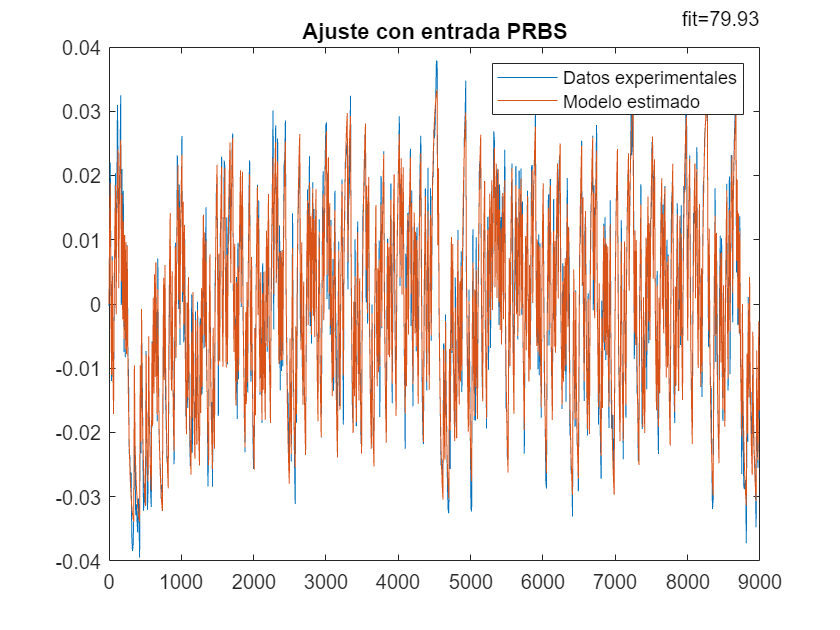

annotation('textbox',[.8 .5 .1 .5], ...
    'String',"fit=" + string(round(fit,2)),'EdgeColor','none')


e=yVal-yest;
mean(e)

ans = 2.8421e-05

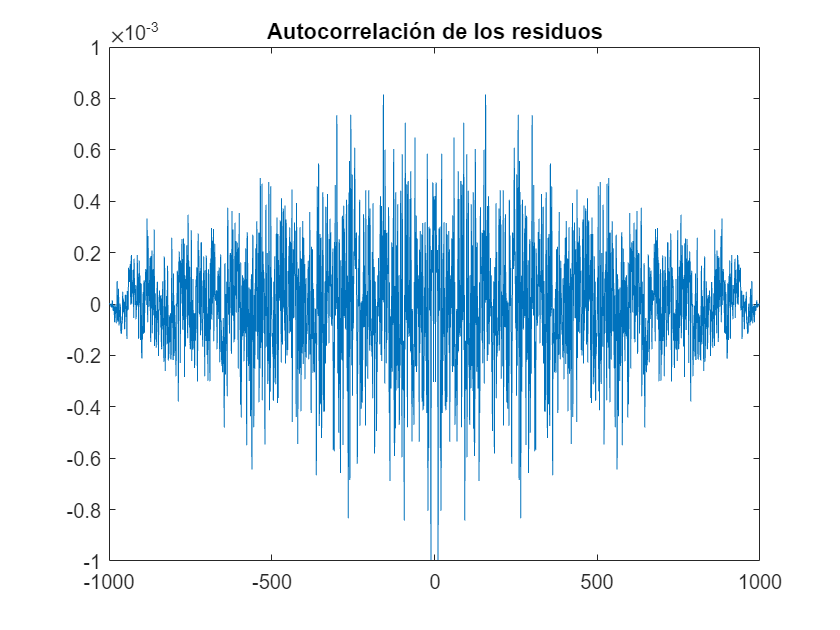

[c, lags] = xcorr(e);
lags(1000)=[];
c(1000)=[];
plot(lags,c)
title("Autocorrelación de los residuos")

yest=lsim(tf([b(i,:) zeros(1,max(na-nb,0))],[1 a(i,:) zeros(1,max(nb-na,0))],'Ts',Ts),uSTEP,t(1:length(uSTEP)));
plot(t(1:length(uSTEP)),[TexpSTEP,yest])
title("Ajuste con entrada escalón")
legend(["Datos experimentales", "Modelo estimado"])
fit=(1-(norm(TexpSTEP-yest)/norm(TexpSTEP-mean(TexpSTEP))))*100

fit = 48.9090

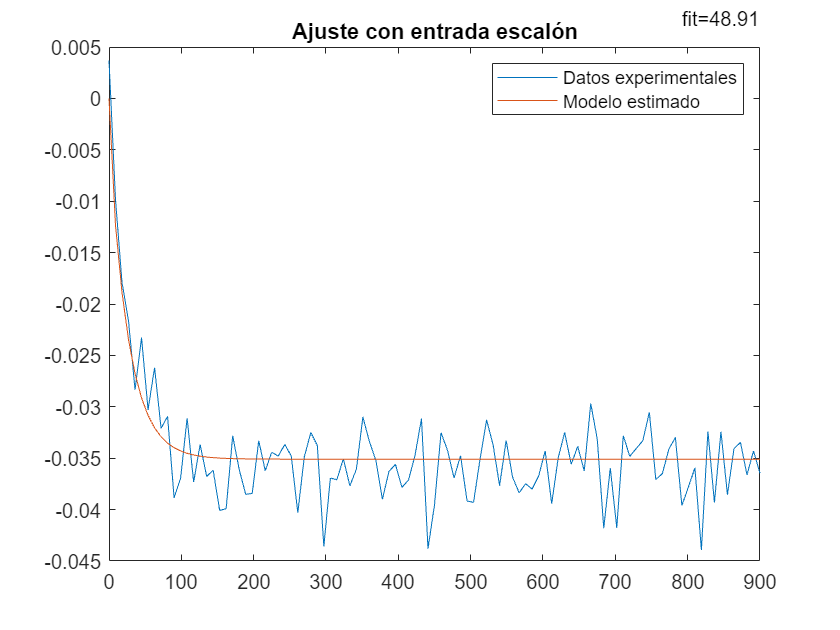

annotation('textbox',[.8 .5 .1 .5], ...
    'String',"fit=" + string(round(fit,2)),'EdgeColor','none')


yest=lsim(tf([b(i,:) zeros(1,max(na-nb,0))],[1 a(i,:) zeros(1,max(nb-na,0))],'Ts',Ts),uSIN,t(1:length(uSIN)));
plot(t(1:length(uSIN)),[TexpSIN,yest])
title("Ajuste con entrada sinusoidal")
legend(["Datos experimentales", "Modelo estimado"])
fit=(1-(norm(TexpSIN-yest)/norm(TexpSIN-mean(TexpSIN))))*100

fit = 86.7487

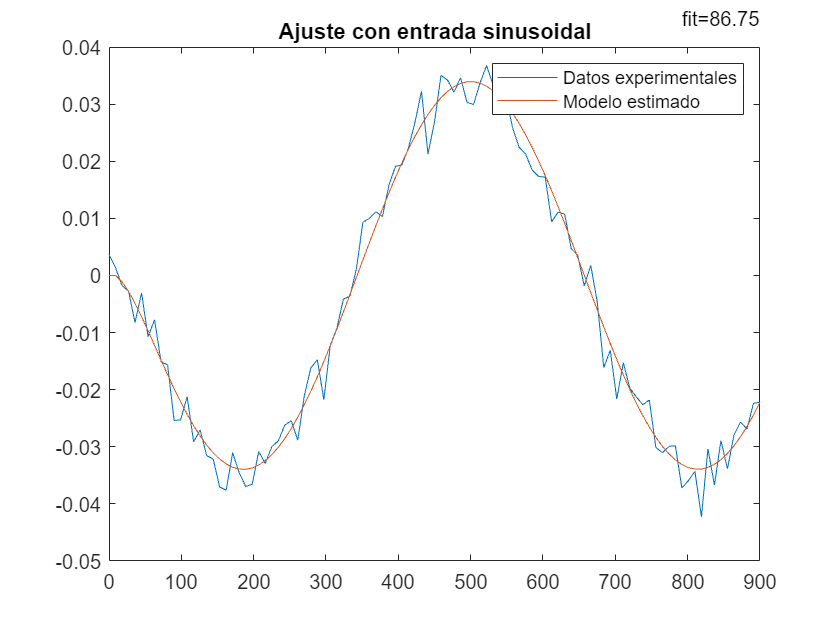

annotation('textbox',[.8 .5 .1 .5], ...
    'String',"fit=" + string(round(fit,2)),'EdgeColor','none')